% define parameters
f1 = 3;                     % frequency 1 (Hz)
f2 = 7;                     % frequency 2 (Hz)
f_max = max(f1, f2);        % maximum frequency component
t = 0:0.001:1;              % fine time grid (for "continuous" signal)
x_t = cos(2*pi*f1*t) + 0.5*cos(2*pi*f2*t);  % continuous signal

% define sampling rates
fs_list = [0.5*f_max, f_max, 2*f_max];

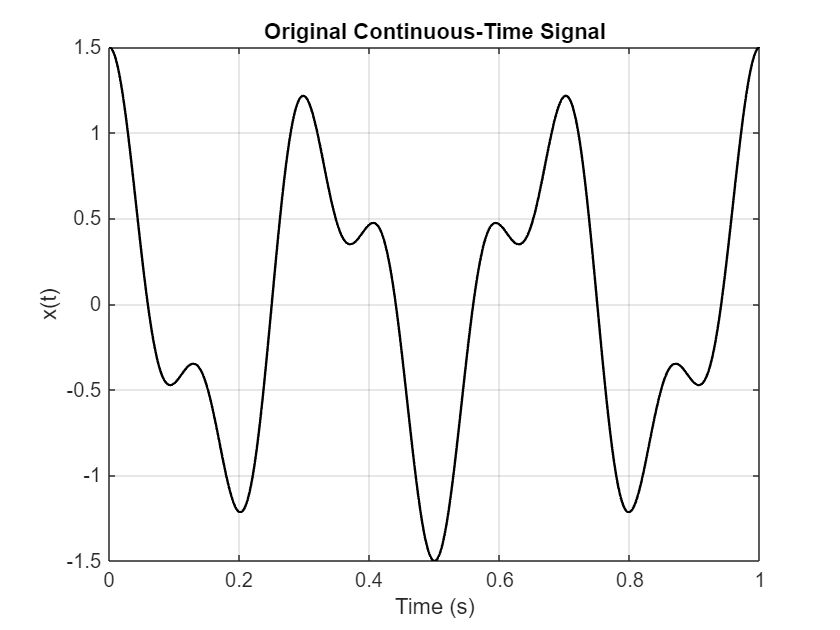

% plot original signal
figure;
plot(t, x_t, 'k-', 'LineWidth', 1.2);
title('Original Continuous-Time Signal');
xlabel('Time (s)');
ylabel('x(t)');
grid on;

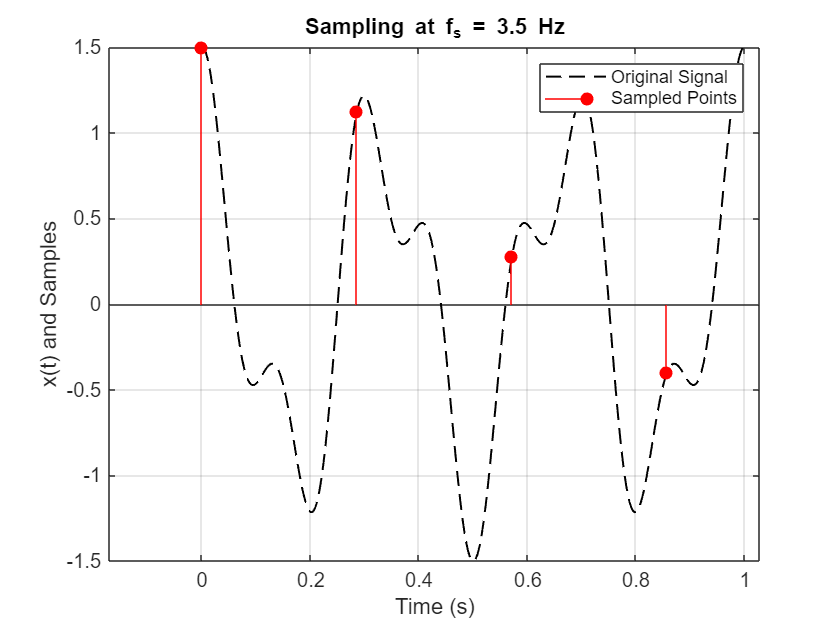

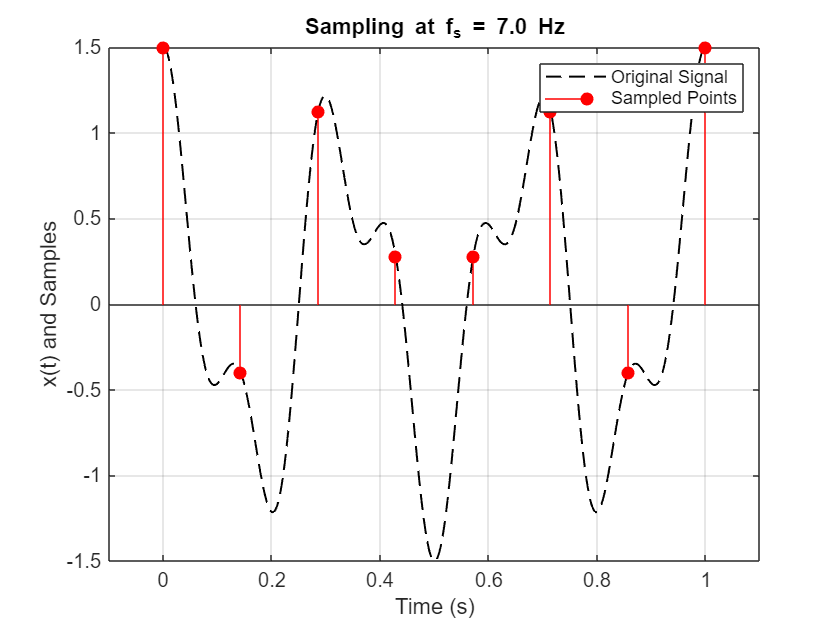

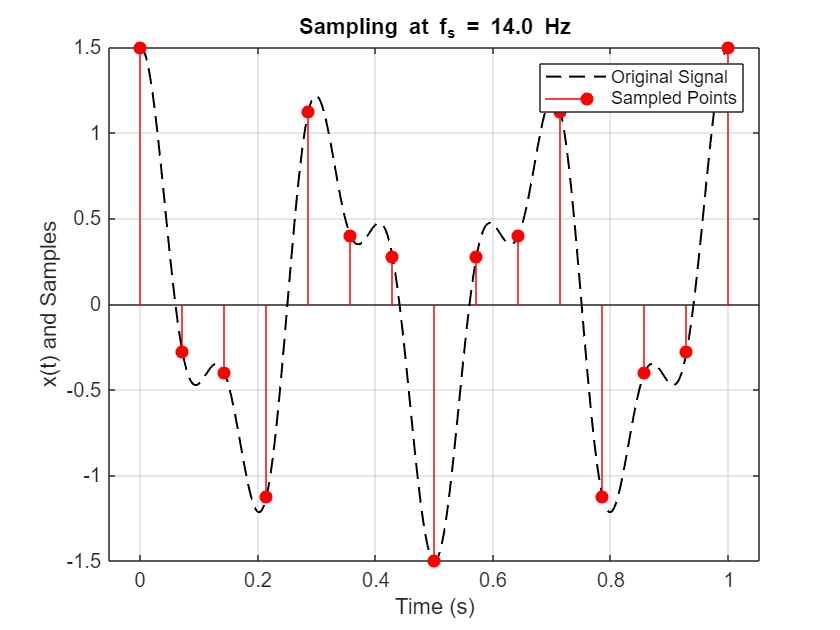

% sample and plot for each fs
for i = 1:length(fs_list)
    fs = fs_list(i);
    
    % call the sampling function
    [t_s, x_s] = sample_signal(t, x_t, fs);

    % plot sampled signal over original
    figure;
    plot(t, x_t, 'k--', 'LineWidth', 1.0); hold on;
    stem(t_s, x_s, 'r', 'filled'); hold off;
    
    title(sprintf('Sampling at f_s = %.1f Hz', fs));
    xlabel('Time (s)');
    ylabel('x(t) and Samples');
    legend('Original Signal', 'Sampled Points');
    grid on;
end